% Template for MXB201 Project Part II.

## Initialisation

clear
d = dir('faces/*.pgm');
N = length(d);
I = imread([d(1).folder, '/', d(1).name]);
[rows,cols] = size(I);
M = rows*cols;
A = zeros(M, N)  % big matrix, whose columns are the images

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

## Read images as columns of the matrix

for j = 1:N
    I = imread([d(j).folder, '/', d(j).name]);
    A(:,j) = I(:);
end

## Calculate and visualise mean face

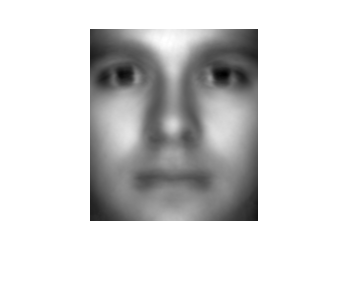

I =   Image with properties:

           CData: [192×168 double]
    CDataMapping: 'scaled'

  Show all properties


MeanA = mean(A, 2);
ReA = reshape(MeanA, [rows, cols]);
I = imshow(ReA, [])

## Calculate mean-centred SVD

MCA = A - MeanA;
[U,Sigma,V] = svd(MCA, 'econ');
sigma = diag(Sigma)

sigma = 1.0e+05 *

    1.4981
    1.3162
    0.8023
    0.5178
    0.4554
    0.4080
    0.3869
    0.3534
    0.2989
    0.2900


## Visualise first 20 eigenfaces

NewU = U(:,1:20);
width = width(NewU)

width = 20

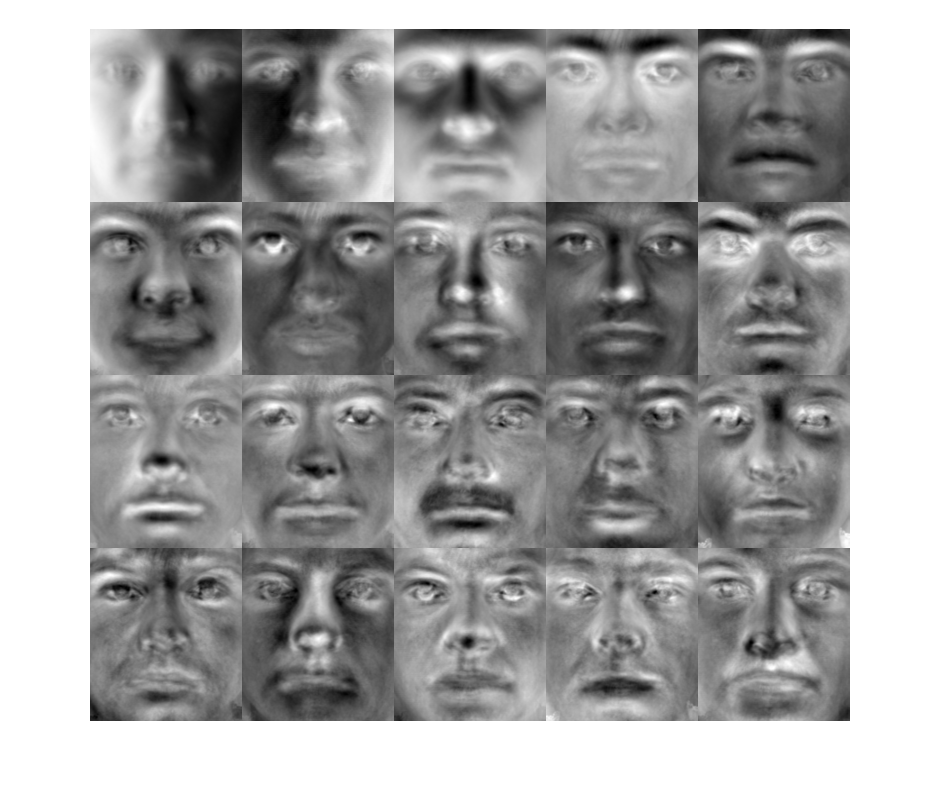

EF = zeros(rows*cols, 1);
ShapedEF = zeros(rows, cols, width);
ShapedEFScaled = zeros(rows, cols, width);

for j = 1:width
    EF = NewU(:, j);
    ShapedEF(:, :, j) = reshape(EF, [rows, cols]);
    ShapedEFScaled(:, :, j) = rescale(ShapedEF(:, :, j), 0, 1);
end

montage(ShapedEFScaled)

## Calculate coordinate vectors

## Demonstrate rudimentary moustache detector